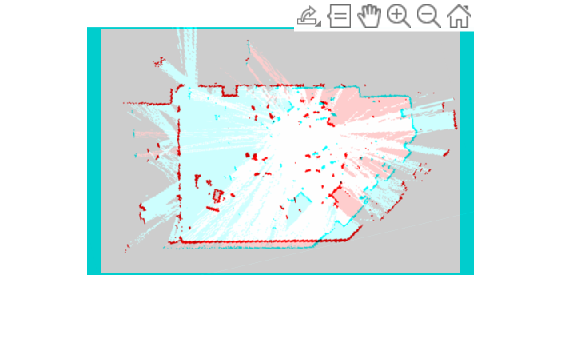

% Load and preprocess the first map
I1 = imread('map_ispace_01_aligned.png');
I1_gray = rgb2gray(I1);
BW1 = double(I1_gray);
corners1 = detectHarrisFeatures(BW1);

% Load and preprocess the second map
I2 = imread('map_ispace_02_aligned.png');
I2_gray = rgb2gray(I2);
BW2 = double(I2_gray);
corners2 = detectHarrisFeatures(BW2);

% Extract feature descriptors for the corners in both maps
[features1, valid_corners1] = extractFeatures(BW1, corners1);
[features2, valid_corners2] = extractFeatures(BW2, corners2);

% Match feature descriptors between the two maps
indexPairs = matchFeatures(features1, features2);

% Retrieve the matched points
matchedPoints1 = valid_corners1(indexPairs(:, 1));
matchedPoints2 = valid_corners2(indexPairs(:, 2));

% Display the matched points
figure;
showMatchedFeatures(BW1, BW2, matchedPoints1, matchedPoints2);

legend('Matched points 1','Matched points 2');

% Estimate the transformation matrix (affine transformation)
[tform, inlierPoints1, inlierPoints2] = estimateGeometricTransform2D(matchedPoints1, matchedPoints2, 'affine');

% Apply the transformation to the first map
I1_transformed = imwarp(BW1, tform, 'OutputView', imref2d(size(BW2)));

% Display the transformed first map and the second map
figure;
imshowpair(I1_transformed, BW2, 'montage');
title('Transformed First Map (Left) and Second Map (Right)');

% Compute the alignment error (e.g., mean squared error)
alignmentError = immse(I1_transformed, BW2);
fprintf('Alignment Error (MSE): %f\n', alignmentError);

% Repeat the process with the transformed maps
% Load and preprocess the transformed first map
I1_transformed_gray = im2gray(I1_transformed);
BW1_transformed = double(I1_transformed_gray);
corners1_transformed = detectHarrisFeatures(BW1_transformed);

% Load and preprocess the second map again (if necessary)
% I2_gray = rgb2gray(I2); % Already preprocessed before

% Extract feature descriptors for the corners in both maps
[features1_transformed, valid_corners1_transformed] = extractFeatures(BW1_transformed, corners1_transformed);
[features2, valid_corners2] = extractFeatures(BW2, corners2);

% Match feature descriptors between the transformed first map and the second map
indexPairs_transformed = matchFeatures(features1_transformed, features2);

% Retrieve the matched points
matchedPoints1_transformed = valid_corners1_transformed(indexPairs_transformed(:, 1));
matchedPoints2 = valid_corners2(indexPairs_transformed(:, 2));

% Display the matched points
figure;
showMatchedFeatures(BW1_transformed, BW2, matchedPoints1_transformed, matchedPoints2);
legend('Matched points 1 (Transformed)','Matched points 2');

xlim([1 502])
ylim([1 296])

% Estimate the transformation matrix (affine transformation)
[tform2, inlierPoints1_transformed, inlierPoints2] = estimateGeometricTransform2D(matchedPoints1_transformed, matchedPoints2, 'affine');

% Apply the transformation to the transformed first map
I1_transformed_final = imwarp(BW1_transformed, tform2, 'OutputView', imref2d(size(BW2)));

% Display the final transformed first map and the second map
figure;
imshowpair(I1_transformed_final, BW2, 'montage');
title('Final Transformed First Map (Left) and Second Map (Right)');

% Compute the alignment error (e.g., mean squared error)
alignmentError_final = immse(I1_transformed_final, BW2);
fprintf('Final Alignment Error (MSE): %f\n', alignmentError_final);
